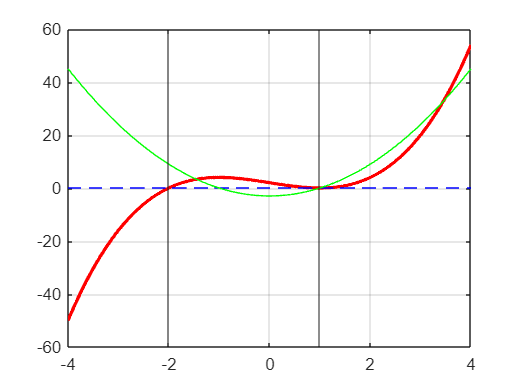

f = @(x) x.^3 - 3.*x + 2;
df = @(x) 3.*x.^2 - 3;

dom = linspace(-4, 4, 1000);
fx = f(dom);
dfx = df(dom);
% whos % print vars

z = @(x)0 * x; % 0 is not valid
zx = z(dom);

figure(1);
plot(dom, fx, "red", LineWidth=2);
hold on;
plot(dom, zx, "blue--");
plot(dom, dfx, "green");
hold off;
ax = gca;
ax.YGrid = 'on';
ax.XGrid = 'on';

x0 = -2.5;
x1 = 1.4;
[alpha0, k0] = newton(x0, f, df, 1e-8);
xline(alpha0);
[alpha1, k1] = newton(x1, f, df, 1e-8);
xline(alpha1);

fprintf('N° iterazioni per x0: %i', k0);

N° iterazioni per x0: 4

fprintf('N° iterazioni per x1: %i', k1);

N° iterazioni per x1: 25